1. Make a function in Matlab to convert ZYX Euler angle to an orientation matrix, and �nd the orintation matrices coincide to $\textrm{ZYX}=\left(0\ldotp 3,0\ldotp 2,0\ldotp 5\right),\left(0\ldotp 7,\pi ,\frac{\pi }{2}\right),\left(\frac{\pi }{3},0,0\right)$

Code:

%Euler angles alpha, beta, and gamma
syms a b g

R = [cos(a)*cos(b), cos(a)*sin(b)*sin(g)-sin(a)*cos(g), ...
    cos(a)*sin(b)*cos(g)+sin(a)*sin(g); sin(a)*cos(b),...
    sin(a)*sin(b)*sin(g) + cos(a)*cos(g),...
    sin(a)*sin(b)*cos(g)-cos(a)*sin(g);...
    -sin(b), cos(b)*sin(g), cos(b)*cos(g)
    ];

Matrices:

For $\textrm{ZYX}=\left(0\ldotp 3,0\ldotp 2,0\ldotp 5\right)$

disp(subs(R,{a,b,g},{0.3,0.2,0.5}))

$$\left(\begin{array}{ccc} \cos\left(\frac{1}{5}\right)\,\cos\left(\frac{3}{10}\right) & \cos\left(\frac{3}{10}\right)\,\sin\left(\frac{1}{2}\right)\,\sin\left(\frac{1}{5}\right)-\cos\left(\frac{1}{2}\right)\,\sin\left(\frac{3}{10}\right) & \sin\left(\frac{1}{2}\right)\,\sin\left(\frac{3}{10}\right)+\cos\left(\frac{1}{2}\right)\,\cos\left(\frac{3}{10}\right)\,\sin\left(\frac{1}{5}\right)\\ \cos\left(\frac{1}{5}\right)\,\sin\left(\frac{3}{10}\right) & \cos\left(\frac{1}{2}\right)\,\cos\left(\frac{3}{10}\right)+\sin\left(\frac{1}{2}\right)\,\sin\left(\frac{1}{5}\right)\,\sin\left(\frac{3}{10}\right) & \cos\left(\frac{1}{2}\right)\,\sin\left(\frac{1}{5}\right)\,\sin\left(\frac{3}{10}\right)-\cos\left(\frac{3}{10}\right)\,\sin\left(\frac{1}{2}\right)\\ -\sin\left(\frac{1}{5}\right) & \cos\left(\frac{1}{5}\right)\,\sin\left(\frac{1}{2}\right) & \cos\left(\frac{1}{2}\right)\,\cos\left(\frac{1}{5}\right) \end{array}\right)$$

For $\textrm{ZYX}=\left(0\ldotp 7,\pi ,\frac{\pi }{2}\right)$

disp(subs(R,{a,b,g},{0.7,pi,pi/2}))

$$\left(\begin{array}{ccc} -\cos\left(\frac{7}{10}\right) & 0 & \sin\left(\frac{7}{10}\right)\\ -\sin\left(\frac{7}{10}\right) & 0 & -\cos\left(\frac{7}{10}\right)\\ 0 & -1 & 0 \end{array}\right)$$

For $\mathrm{ZYX}=\left(\frac{\pi }{3},0,0\right)$

disp(subs(R,{a,b,g},{pi/3,0,0}))

$$\left(\begin{array}{ccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

2. Make a function in Matlab to construct SE(3) from rotation matrix and translation vector, and make a function to multiply two SE(3)s and make a function to invert SE(3), then find the transformation matrix of frame {3} to frame {0} $T_{03}$ from the following Euler angles and translation vectors:

Code:

%Translation variables which make up the translation vector
syms p1 p2 p3
P = [p1;  p2; p3]

$$P = \left(\begin{array}{c} p_{1}\\ p_{2}\\ p_{3} \end{array}\right)$$

T =[R, P;
    0 0 0 1]

$$T = \left(\begin{array}{cccc} \cos\left(a\right)\,\cos\left(b\right) & \cos\left(a\right)\,\sin\left(b\right)\,\sin\left(g\right)-\cos\left(g\right)\,\sin\left(a\right) & \sin\left(a\right)\,\sin\left(g\right)+\cos\left(a\right)\,\cos\left(g\right)\,\sin\left(b\right) & p_{1}\\ \cos\left(b\right)\,\sin\left(a\right) & \cos\left(a\right)\,\cos\left(g\right)+\sin\left(a\right)\,\sin\left(b\right)\,\sin\left(g\right) & \cos\left(g\right)\,\sin\left(a\right)\,\sin\left(b\right)-\cos\left(a\right)\,\sin\left(g\right) & p_{2}\\ -\sin\left(b\right) & \cos\left(b\right)\,\sin\left(g\right) & \cos\left(b\right)\,\cos\left(g\right) & p_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Function to multiply two symbolic equations

%function Tres = Tmul(T)
%    Tres = T * T;
%end
%
%function Tres = Tinv(T)
%    R = T(1:3,1:3);
%    p = T(1:3,4);
%    
%    Tres =[R.', -R.' * p;
%    0 0 0 1];
%end

Matrix:

% frame{0}: Euler angle ZYX = (0, 0, 0), position: (0, 0, 0)
T0 = subs(T,{a,b,g,p1, p2, p3},{0,0,0,0,0,0});
% frame{0}�>frame{1}: Euler angle ZYX = (0.3, 0.2, 0.5), position: (0.4, 0.8, 1.2).
T01 = subs(T,{a,b,g,p1, p2, p3},{0.3,0.2,0.5,0.4,0.8,1.2});
% frame{1}�>frame{2}: Euler angle ZYX = (0.7, π, π/2), position: (-0.4, 0.5, 1.0).
T12 = subs(T,{a,b,g,p1, p2, p3},{0.7,pi,pi/2,-0.4,0.5,1.0});
% frame{2}�>frame{3}}: Euler angle ZYX = (π/3, 0, 0), position: (0.5, -0.8, 1.2).
T23 = subs(T,{a,b,g,p1, p2, p3},{pi/3,0,0,0.5,-0.8,1.2});

T01 = Tmul(T0, T01);
T02 = Tmul(T01, T12);
T03 = Tmul(T02, T23);
T30 = Tinv(T03);

digits(8)

disp("Frame 0->1")

Frame 0->1


disp(vpa(T01))

$$\left(\begin{array}{cccc} 0.93629336 & -0.1683503 & 0.30824165 & 0.4\\ 0.28962948 & 0.8665341 & -0.40648914 & 0.8\\ -0.19866933 & 0.46986895 & 0.86008934 & 1.2\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

disp("Frame 0->2")

Frame 0->2


disp(vpa(T02))

$$\left(\begin{array}{cccc} -0.60766242 & -0.30824165 & 0.73193816 & 0.24954915\\ -0.77975744 & 0.40648914 & -0.47617741 & 0.71092612\\ -0.1507472 & -0.86008934 & -0.48736189 & 2.3744915\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

disp("Frame 0->3")

Frame 0->3


disp(vpa(T03))

$$\left(\begin{array}{cccc} -0.57077631 & 0.37213027 & 0.73193816 & 1.070637\\ -0.037848802 & 0.87853432 & -0.47617741 & -0.57555679\\ -0.82023282 & -0.29949376 & -0.48736189 & 2.4023551\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

disp("Frame 3->0")

Frame 3->0


disp(vpa(T30))

$$\left(\begin{array}{cccc} -0.57077631 & -0.037848802 & -0.82023282 & 2.5598007\\ 0.37213027 & 0.87853432 & -0.29949376 & 0.82672032\\ 0.73193816 & -0.47617741 & -0.48736189 & 0.1131091\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

3. Plot above frame{1}, frame{2}, frame{3} in global coordinate frame{0}. You can use the given "drawCoordinat3D.m" funtion to plot and refer to "matlab_test3D.m" for instruction.

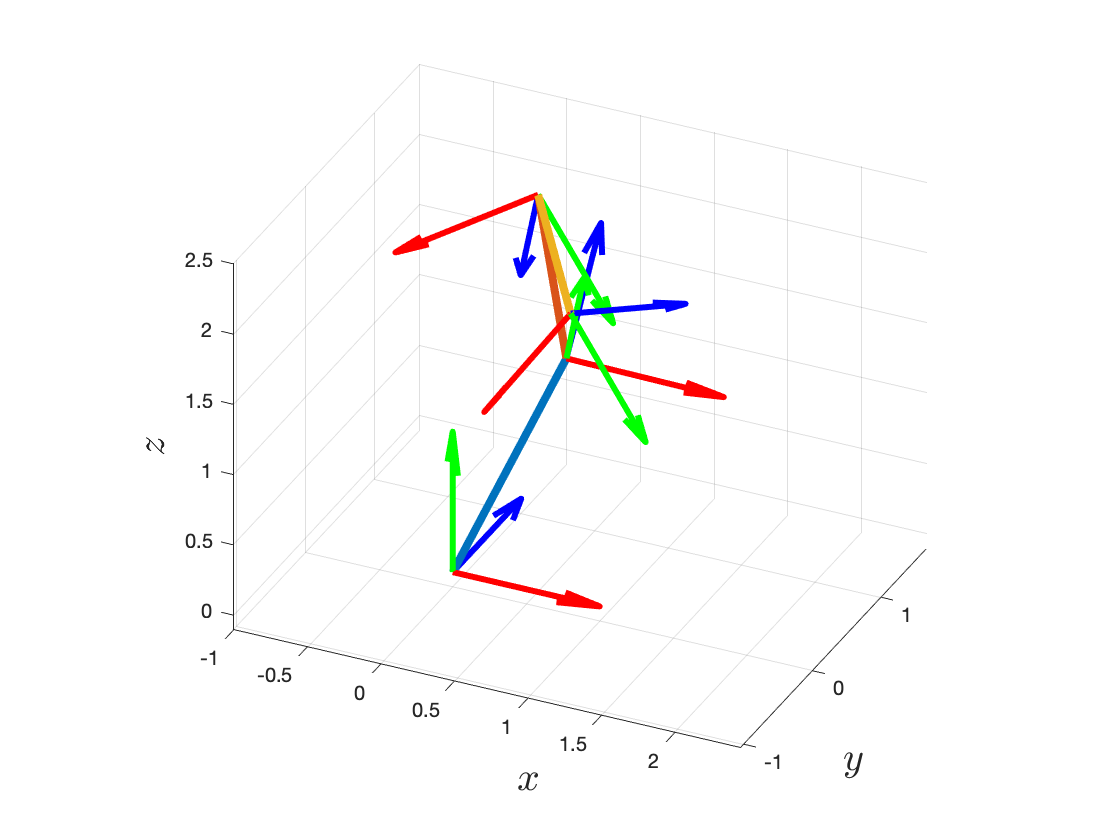

[R0, P0] = Textract(T0);
[R1, P1] = Textract(T01);
[R2, P2] = Textract(T02);
[R3, P3] = Textract(T03);

hold on
grid on

drawLine3D([0;0;0], P1.');
drawLine3D(P1, P2.');
drawLine3D(P2, P3.');

drawCoordinate3D(R0, P0.')
drawCoordinate3D(R1, P1.')
drawCoordinate3D(R2, P2.')
drawCoordinate3D(R3, P3.')
hold off

xlabel('$x$','interpreter','latex','fontsize',20)
ylabel('$y$','interpreter','latex','fontsize',20)
zlabel('$z$','interpreter','latex','fontsize',20)
axis equal
view(25,30)

4. Show the animation of frame EE at frame 3. Let frame EE has the same rotation matrix as frame 3 and the translation vector is [x, y, z] where x=0.1sin(ωt)+0.05, y=0.3cos(ωt)+0.08, z=sin(ωt)+0.5. t lasts a few seconds. Refer to "animation2D.m" for instruction. Please provide several screen shots to represent the animation.

figure
clf

[R, in2] = Textract(Frame3);

omega = pi

omega = 3.1416

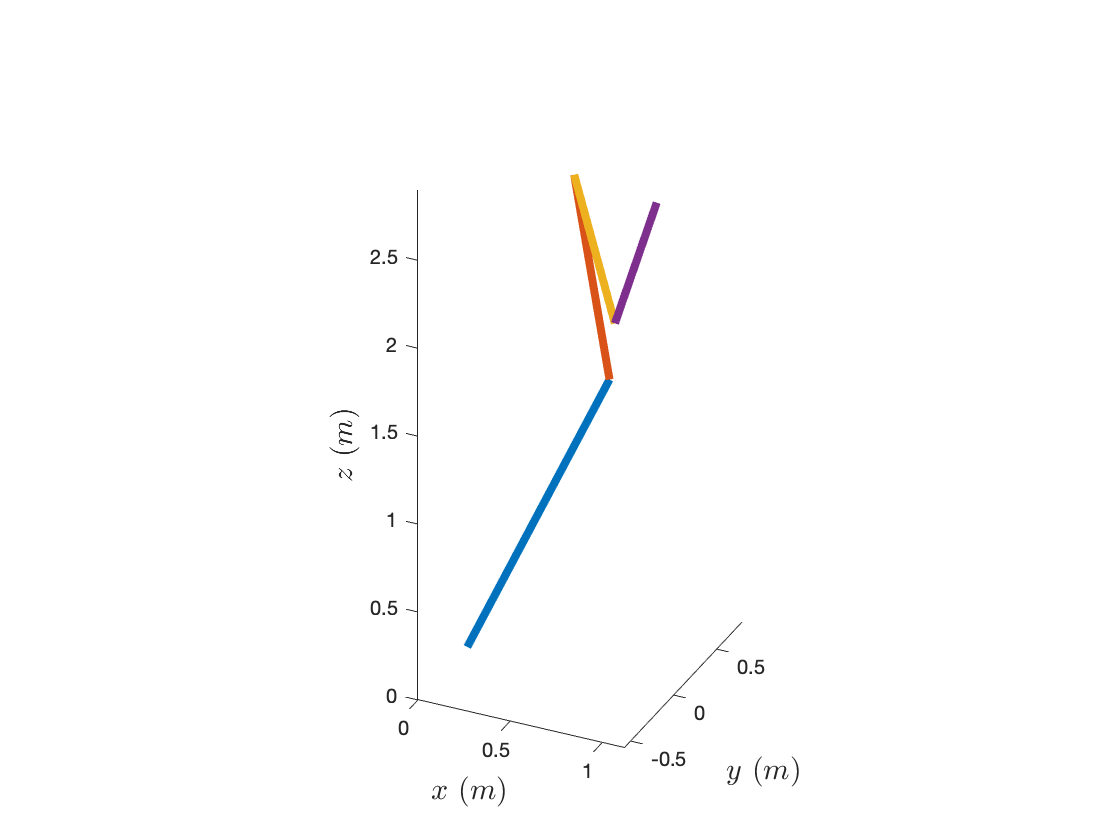


t = 0;

for i=1:100
    t = t+0.02;
    theta = omega*t;
    
    x= 0.1 * sin(theta)+0.05;
    y= 0.3 * cos(theta)+0.08;
    z = sin(theta)+0.5;
    hold off
    drawLine3D([0;0;0], P1.');
    
    hold on
    drawLine3D(P1.', P2.');
    drawLine3D(P2.', P3.');
    drawLine3D(P3.', P3.' + [x; y; z;].');
    
    % fix the range of axis
    axis([-3 3 -3 3 0 3])
    
    % axis label
    xlabel('$x\  (m)$','interpreter','latex','fontsize',15)
    ylabel('$y\  (m)$','interpreter','latex','fontsize',15)
    zlabel('$z\  (m)$','interpreter','latex','fontsize',15)
    pause(.01);
    hold off
    axis equal
    view(25,30)
end

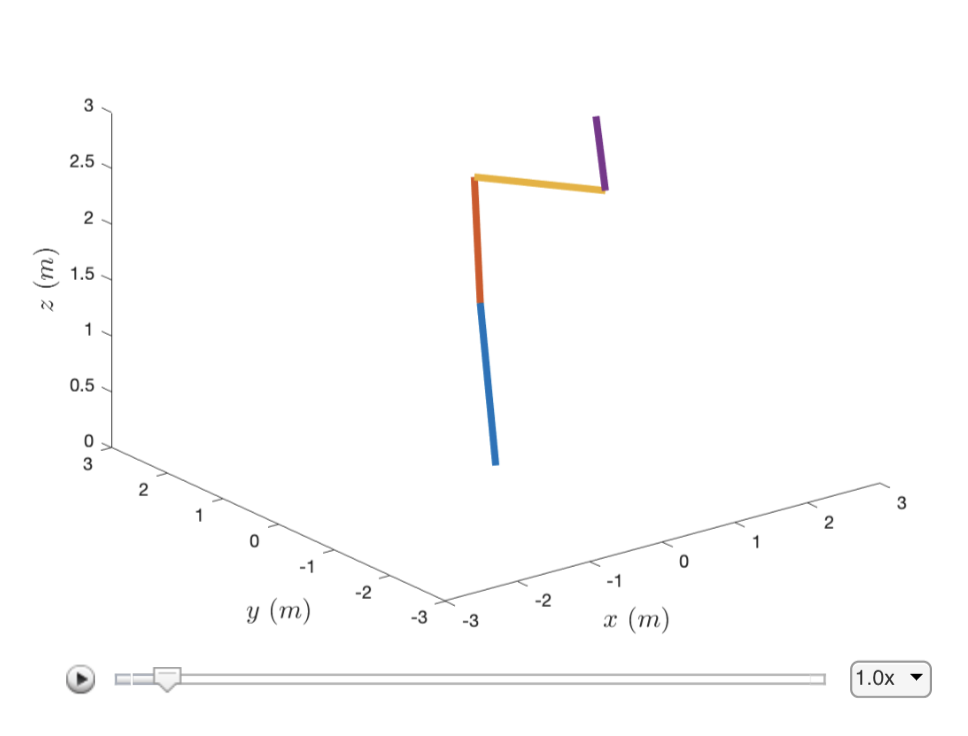

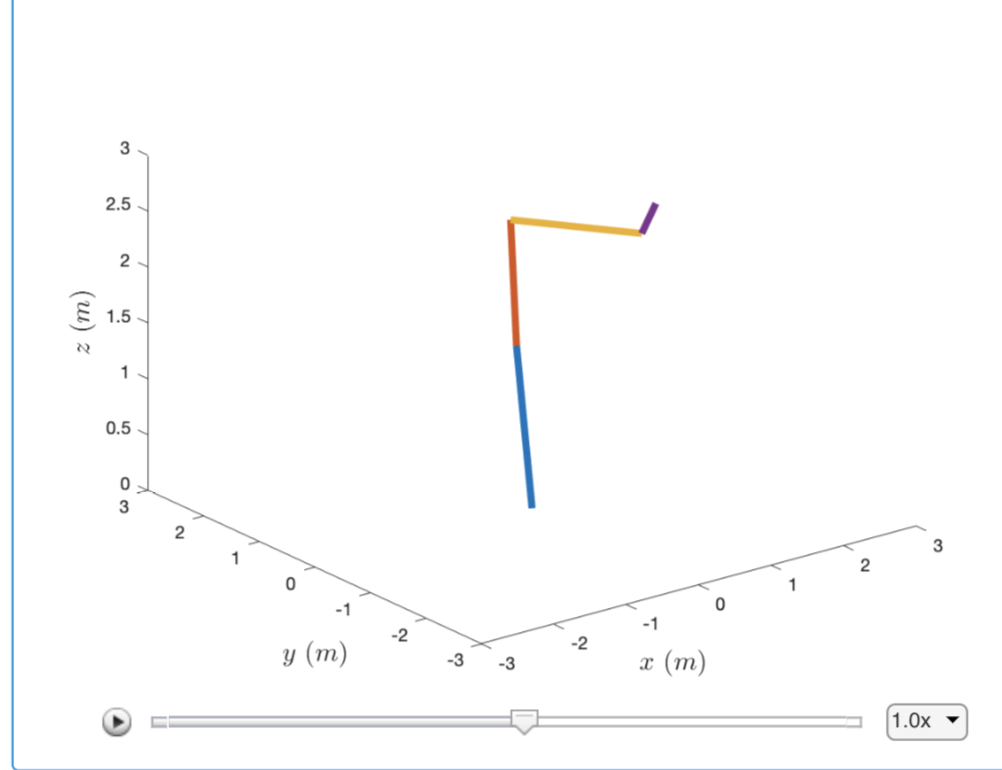

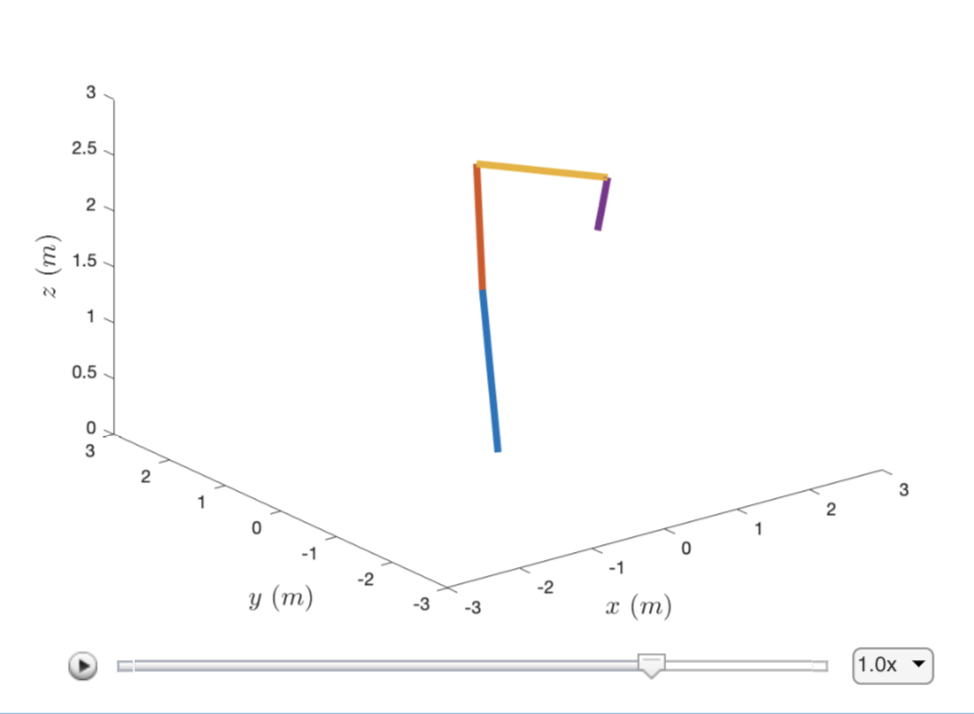

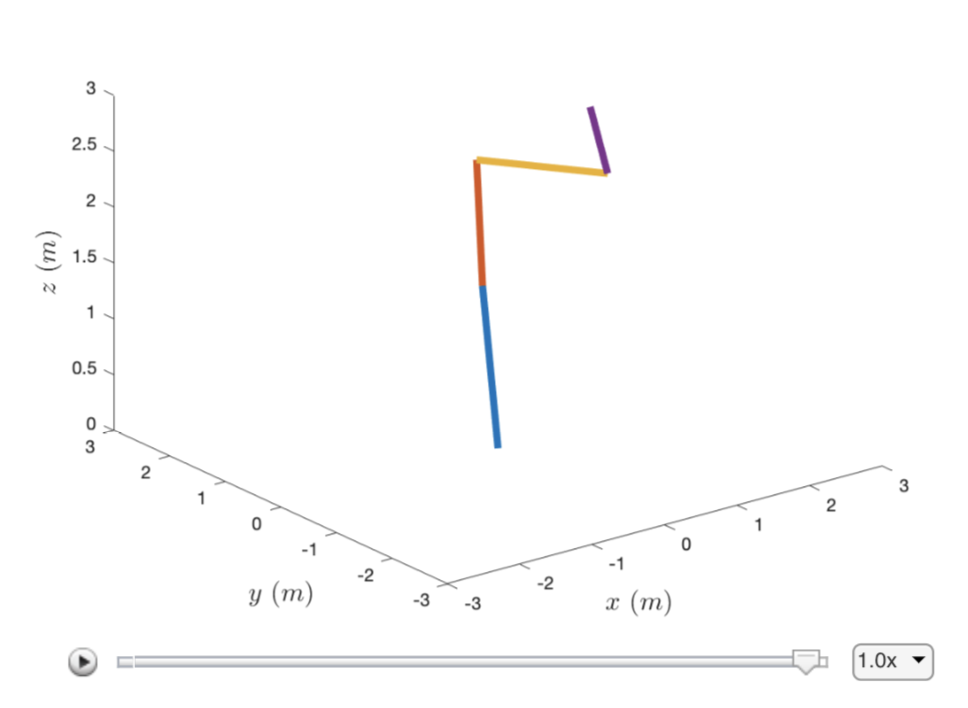

function Tres = Tmul(T1, T2)
    Tres = T1 * T2;
end

function Tres = Tinv(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
    
    Tres =[R.', -R.' * p;
    0 0 0 1];
end

function [R,p] = Textract(T)
    R = T(1:3,1:3);
    p = T(1:3,4);
end